clear all

Generate equally spaced mesh for $x\in[0,5]$

Nx=60;Ny=20;
xi=linspace(0,5,Nx);
Deltax=xi(2)-xi(1);

Creating the derivative matrix and differentiate the function in the x direction

b=zeros(Nx,1);
b(1)=-2;
b(end)=2;

a=-ones(Nx-1,1);
a(end)=-2;

c=ones(Nx-1,1);
c(1)=2;
Derivx=(diag(a,-1)+diag(b)+diag(c,1))/(2*Deltax);

Now let's see if we can us this for 2d functions.

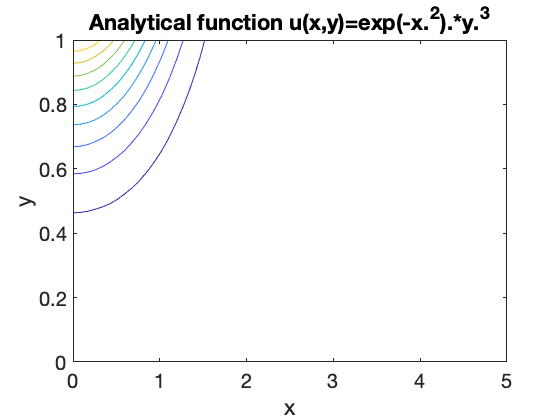

u=@(x,y)exp(-x.^2).*y.^3;
ux=@(x,y)-2.*x.*exp(-x.^2).*y.^3;
xi=linspace(0,5,Nx);
yi=linspace(0,1,Ny);
[Xi,Yi]=meshgrid(xi,yi);
figure
contour(Xi,Yi,u(Xi,Yi))
xlabel('x');ylabel('y')
title('Analytical function u(x,y)=exp(-x.^2).*y.^3')

Apply the derivative matrix on every row of the 2d [u] matrix

uij=u(Xi,Yi);
% Need to transpose uij because need the data in the x direction to be in
% rows rather than columns. 
dxuij=Derivx*transpose(uij);

% Transpose back to have data in the x direction to be in columns. 
dxuij=transpose(dxuij);


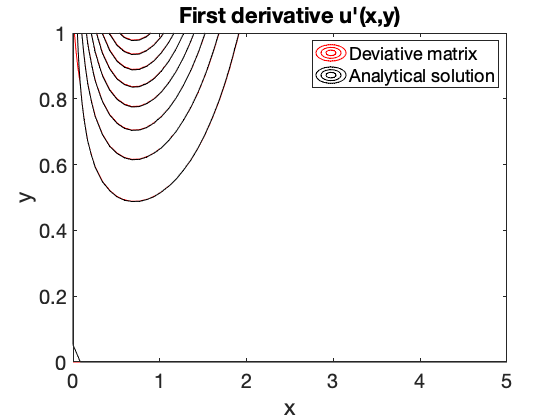

figure
contour(Xi,Yi,dxuij,'r-')
hold on
contour(Xi,Yi,ux(Xi,Yi),'ko')
hold off
xlabel('x');ylabel('y')
legend('Deviative matrix','Analytical solution')
title("First derivative u'(x,y)")

In the plot above, the contour lines of the analytical $\partial u/\partial x$ coincide with the contour lines of the approximate derivative.  So the derivative matrix is OK. 

Now we will construct the Derivative matrix where $u(x,y)$ is arranged as a column vector $\{u\}$.  You should be able to calculate the derivative of $\{u\}$ by just performing the matrix vector multiplication


$$\{u_x\}=[D]\{u\}$$


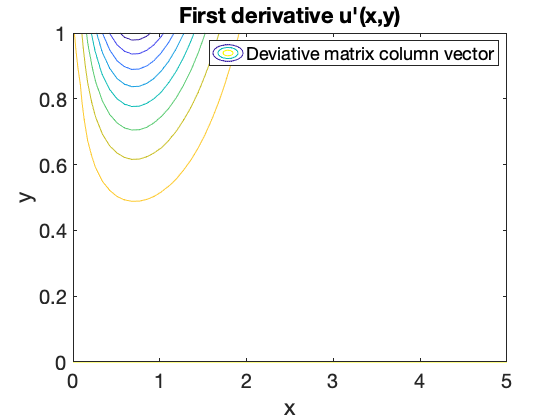

Derivx2D=kron(eye(Ny),Derivx);
%uxnum=Derivx2D*reshape(u(Xi,Yi)',[Ny*Nx 1]);
uxnum=Derivx2D*reshape(transpose(uij),[Ny*Nx 1]);
figure
contour(Xi,Yi,reshape(uxnum,Nx,Ny)');
xlabel('x');ylabel('y')
legend('Deviative matrix column vector')
title("First derivative u'(x,y)")

Now try to get $f_i=f(x_i)=\left\{f\right\}$ by solving $\left[D\right]\left\{f\right\}=\left\{df/dx\right\}$.  

rhs=reshape(ux(Xi,Yi)',[Nx*Ny 1]);
linsolve(Derivx2D,rhs);

This fails miserably!  How about we try with the \ operator in MATLAB

Derivx2D\rhs;

Fail as well! What is wrong??

We should define boundary condition.  If not we cannot solve for a unique $f(x)$.  Modify the Deriv matrix and also dfi to specify the boundary condition $u(x=0)=y^3$

for i=1:Ny
    Derivx2D((i-1)*Nx+1,:)=0.0;
    Derivx2D((i-1)*Nx+1,(i-1)*Nx+1)=1.0;
    rhs((i-1)*Nx+1)=yi(i).^3;
end

Now try solving for $\left\{f\right\}$

unumeric=linsolve(Derivx2D,rhs);

Now plot the solution and compare with the "real" $u(x,y)=y^3e^{-x^2}$.

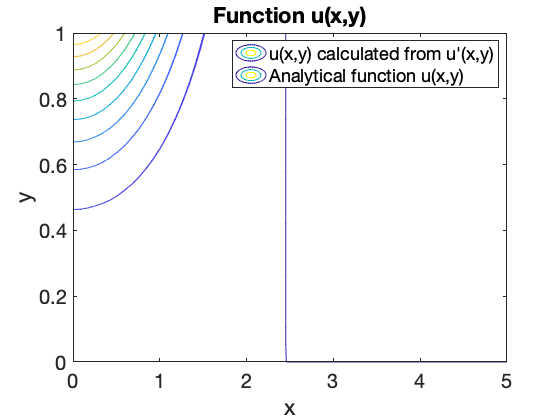

figure
unumericmatrix=reshape(unumeric,Nx,Ny)';
contour(Xi,Yi,unumericmatrix);
hold on
contour(Xi,Yi,u(Xi,Yi));
xlabel('x');ylabel('y')
legend("u(x,y) calculated from u'(x,y)", "Analytical function u(x,y)")
title("Function u(x,y)")